x=[1,2,3,4,5,6,7,8,9,10,11,12];
x=x';

y=[0.9,2.1,4.3,6.8,9.4,12.1,15.0,18.2,21.5,25.0,28.6,32.3];
y=y';

plot(x,y,'ro');
title('Puntos Experimentales');

%modelo lineal

% X=[x,ones(numel(x),1)];
% I = X\y
% y_modelo = (I(1,:)*x)+I(2,:)
% plot(x, y_modelo, '--r')
% hold on
% plot(x,y,'blue')

%modelo polinomial

% X=[x.^2,x,ones(numel(x),1)];
% I = X\y
% y_modelo = (I(1,:)*(x.^2))+(I(2,:)*x)+(I(3,:));
% plot(x, y_modelo, '--r')
% hold on
% plot(x,y,'blue')

%modelo exponencial

X=[x,ones(numel(x),1)];
Y=log(y);
I = X\Y

I =     0.2908
    0.3992


A = exp(I(2,:));
y_modelo = A*exp(I(1,:)*x)

y_modelo =     1.9936
    2.6664
    3.5663
    4.7698
    6.3794
    8.5323
   11.4116
   15.2626
   20.4133
   27.3021


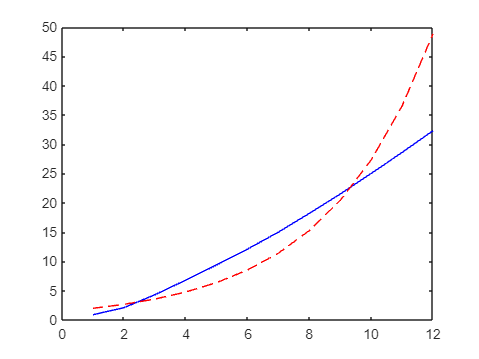

plot(x,y,'blue')
hold on
plot(x, y_modelo, '--r')